N = 300;          %主链长度
N1 =150;         %支链1连接位置
N0 =2;           %每个支链长度（不含分支点）
L = 4;            %支链间距（含两端点）
J = 1;            %相互作用强度
loop = true;
tspan = [0,500];



%定义哈密顿量
%主链编号为1~N，支链编号为N+1~N+N0,N+N0+1~N+2*N0

H = zeros(N+2*N0,N+2*N0);         %初始化

%主链相互作用
for ii = 1:(N-1)
    H = interaction(H,ii,ii+1,J);
end
if loop == true
    H = interaction(H,N,1,J);
end

%支链相互作用
for ii = 1:N0-1
    H = interaction(H,N+ii,N+ii+1,J);
    H = interaction(H,N+N0+ii,N+N0+ii+1,J);
end

%连接处相互作用
H = interaction(H,N1,N+1);
H = interaction(H,N1+L-1,N+N0+1);

%在两端加上轻微的衰减，防止反射
%衰减不能太强，否则会直接反射
for ii = 1:50
    H(ii,ii) = -0.1i;
end
for ii = (N-50):N
    H(ii,ii) = -0.1i;
end


opts = odeset('Reltol',1e-8,'AbsTol',1e-10);
tic
k = pi*[1/3 1/9 2/9 4/9];
psi = cell(length(k),1);
t = cell(length(k),1);
locations = [(N+N0-(0:N0-1)) N1:(N1+L-1) (N+N0+1):(N+2*N0)];  %按顺序排列的子链粒子
psi0 = initpsi(N,N0,N1,L,k(1));
[t{1},psi{1}] = ode113(@(t,psi) -1i*H*psi, tspan, psi0, opts);
p = vecnorm(psi{1}(:,locations),2,2);        %粒子在选定位置出现概率之和
plot(t{1},p)
hold on
for ii = 2:length(k)
psi0 = initpsi(N,N0,N1,L,k(ii));
[t{ii},psi{ii}] = ode113(@(t,psi) -1i*H*psi, tspan, psi0, opts);
p = vecnorm(psi{ii}(:,locations),2,2);        %粒子在选定位置出现概率之和
plot(t{ii},p)
end
toc

历时 24.352542 秒。


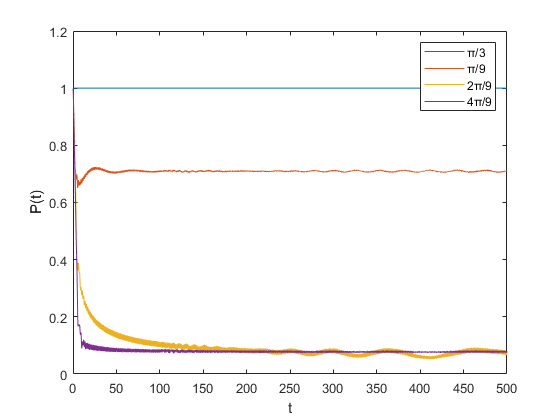

hold off
legend('π/3','π/9','2π/9','4π/9')
%legend('π/2','π/130','16π/65','7π/26')
xlabel('t')
ylabel('P(t)')

%axis([0 100 0.8 1.05])

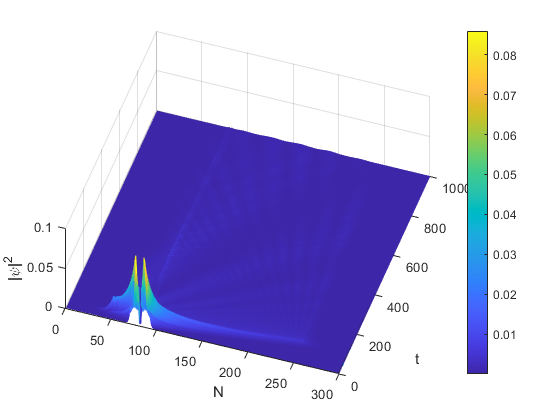

plotpsi(psi{1}(100:end,1:N),t{1}(100:end),N)

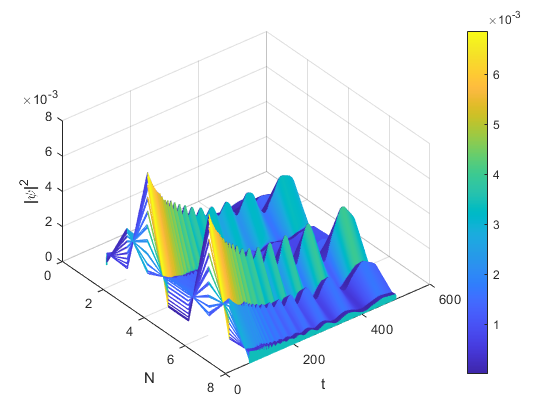

plotpsi(psi{3}(1000:end,locations),t{3}(1000:end),length(locations))

tspan = linspace(0,100,500);
locations = [(N+N0-(0:N0-1)) N1:(N1+L-1) (N+N0+1):(N+2*N0)];  %按顺序排列的子链粒子
psi0 = initpsi(N,N0,N1,L,k(3));
psi = zeros(500,N+2*N0);
tic
ii = 1;
for t = tspan
    psi(ii,:) = transpose(expm(-1i*H*t)*psi0);
    ii = ii + 1;
end
toc

历时 15.697780 秒。


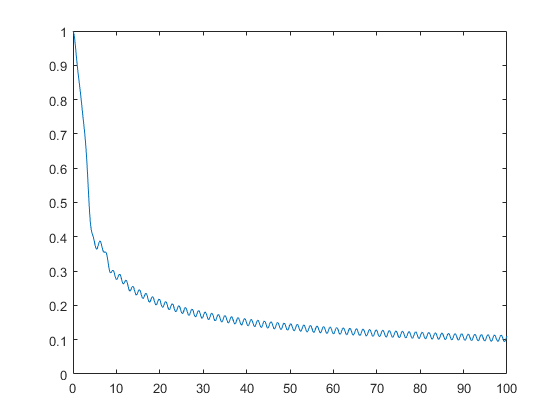

p = vecnorm(psi(:,locations),2,2);        %粒子在选定位置出现概率之和
plot(tspan,p)

function psi0 = initpsi(N,N0,N1,L,k)
Lambda = L+2*N0;              %总长度
psi1 = sin(k*(1:Lambda));
psi1 = psi1/(norm(psi1));
psi0 = zeros(N+2*N0,1);
locations = [(N+N0-(0:N0-1)) N1:(N1+L-1) (N+N0+1):(N+2*N0)];  %按顺序排列的子链粒子
psi0(locations) = psi1;
end

